# RL agent Donor agnostic no penalty no u donors table

Table linear basis function as value function

format shortG
seed = 1

seed =      1


epsilondecay = 0.00125;
numepisodes = 2000;
tilesperday = 72;
learnrate = 0.01;
agentnumber = 32;

No U donors

allmodelfoldincs = readmatrix("allmodelfoldincs.txt")

allmodelfoldincs =             1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1
            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1     

modelinitcons = readmatrix("modelinitcons.txt")

modelinitcons =       400000      420000      440000      460000      480000      500000      520000      540000      560000      580000      600000


rawfoldincs = readmatrix("rawfoldincs.txt")

rawfoldincs =             1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1
        1.078         1.53        1.358        1.548        1.052        1.052         0.94        0.718       1.0855         1.19        1.131       1.5582        1.952       1.1377       1.1583       1.0556        0.962        1.076         0.94         0.94         1.13          0.9         0.83        0.865         1.05         0.94         1.17         1.13         0.94         0.38          0.6       0.7625            1            1            1            1            1
       6.1224       4.

rawinitcons = readmatrix("rawinitcons.txt")

rawinitcons =       500000      500000      500000      500000      500000      500000      500000      500000      500000      500000      500000      500000      500000      500000      360000      360000      500000      500000      100000      100000      100000      100000      100000      100000      100000      100000      100000      100000      100000      100000      100000      100000      500000      500000      500000      500000      500000


truecon = readtable("true con.xlsx");
truecon(:,1)=[];
rawdonornames = truecon.Properties.VariableNames;
rawdonornames = string(rawdonornames);
rawdonornames = strrep(rawdonornames,"_","-")

rawdonornames = 1×37 string array
    "T054-1"    "T046-1"    "T051-1"    "T062-1"    "T031-1"    "T031-2"    "T052-1"    "T038-1"    "T036-1"    "T036-2"    "T036-3"    "T066-1"    "T066-2"    "T066-3"    "UA4-1"    "UA4-2"    "UA4-3"    "UA4-4"    "UA4-5"    "UA4-6"    "UA4-7"    "UA4-8"    "UA4-9"    "UA4-10"    "UA4-11"    "UA4-12"    "UA4-13"    "UA141-1"    "UA141-2"    "UA141-3"    "UA141-4"    "UA141-5"    "UA6-1"    "UA6-2"    "UA6-3"    "UA6-4"    "UA6-5"


% rawdonornames = ["T054","T046","T051","T062","T031","T031","T052","T038","T036","T036","T036","T066","T066","T066","UA4","UA4","UA4","UA4","UA4","UA4","UA4","UA4","UA4","UA4","UA4","UA4","UA4","UA141","UA141","UA141","UA141","UA141","UA6","UA6","UA6","UA6","UA6"]
donorlist = ["T054","T046","T051","T062","T031","T052","T038","T036","T066","UA4","UA141","UA6"]

donorlist = 1×12 string array
    "T054"    "T046"    "T051"    "T062"    "T031"    "T052"    "T038"    "T036"    "T066"    "UA4"    "UA141"    "UA6"


donoridxmap = {1,2,3,4,5:6,7,8,9:11,12:14,15:27,28:32,33:37}

donoridxmap = 1×12 cell array
    {[1]}    {[2]}    {[3]}    {[4]}    {[5 6]}    {[7]}    {[8]}    {[9 10 11]}    {[12 13 14]}    {[15 16 17 18 19 20 21 22 23 24 25 26 27]}    {[28 29 30 31 32]}    {[33 34 35 36 37]}


Run training and validation 

Randomization: 

-6:3 training:validation split for tall the T donors

u donors never included

numdonors = 6

All validation set printed

initializedatasets(seed,allmodelfoldincs,modelinitcons,rawfoldincs,rawinitcons,rawdonornames,donoridxmap,donorlist);

trainingset = 1×6 string array
    "T054"    "T046"    "T051"    "T062"    "T031"    "T038"


validationset = 1×6 string array
    "T052"    "T036"    "T066"    "UA4"    "UA141"    "UA6"



numdonors = 6;

qagent = qinittraining(seed,numdonors,epsilondecay,numepisodes,learnrate,tilesperday);

save("Hyperparameter Tuning/LBF/agent_2481"+agentnumber,"qagent")

rawfoldincs(:,15:end) = []

rawfoldincs =             1            1            1            1            1            1            1            1            1            1            1            1            1            1
        1.078         1.53        1.358        1.548        1.052        1.052         0.94        0.718       1.0855         1.19        1.131       1.5582        1.952       1.1377
       6.1224       4.6158       4.2724       6.3406        5.555        5.555       6.1277       6.0724        4.147       5.0623       4.6189       3.9479       4.8302       4.2567
       5.4756       4.7525        3.882        3.027          4.5          4.5       3.2186       3.4439       4.1462       6.0479       4.0482       5.3647       6.5694       3.4422
          NaN       2.3012       1.6283       1.3062       2.5181       2.5181       3.6119       2.2886       3.4762       4.1757       2.3177       2.2001       2.0197       2.5865
          NaN          NaN       1.3772       1.2429          NaN      

rawinitcons(15:end) = []

rawinitcons =       500000      500000      500000      500000      500000      500000      500000      500000      500000      500000      500000      500000      500000      500000


env3 =   modelEnv241 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T054-1"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×66 double]
                     numdonors: 8
                     foldExMap: [4×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


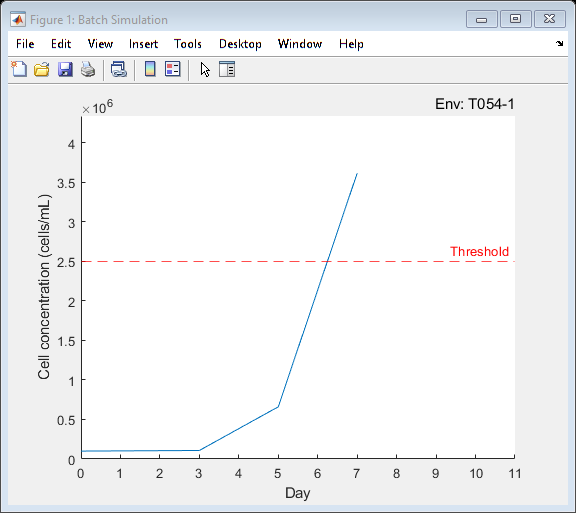

env3 =   modelEnv241 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T046-1"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×66 double]
                     numdonors: 8
                     foldExMap: [5×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


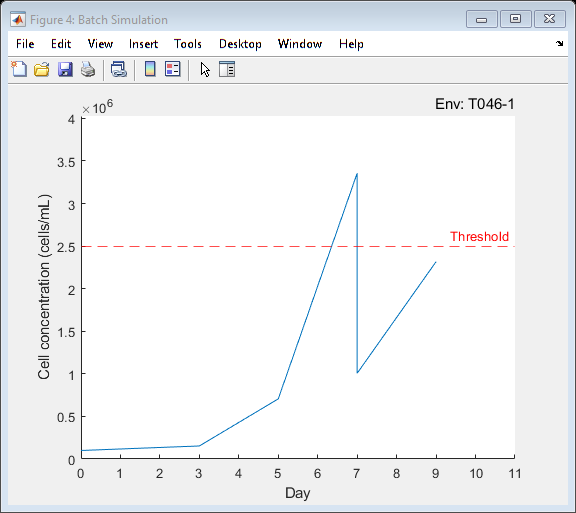

env3 =   modelEnv241 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T051-1"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×66 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


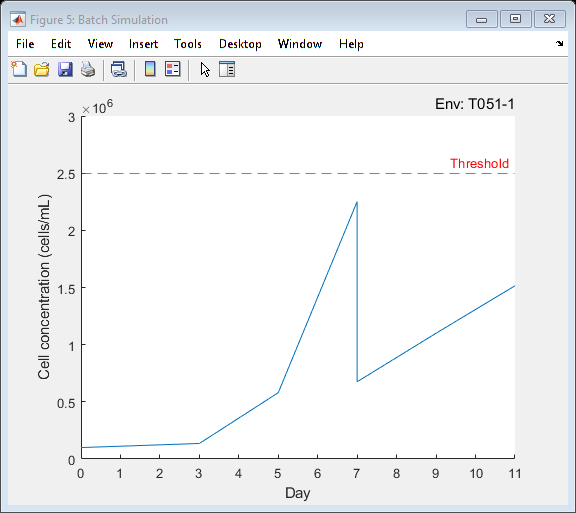

env3 =   modelEnv241 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T062-1"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×66 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


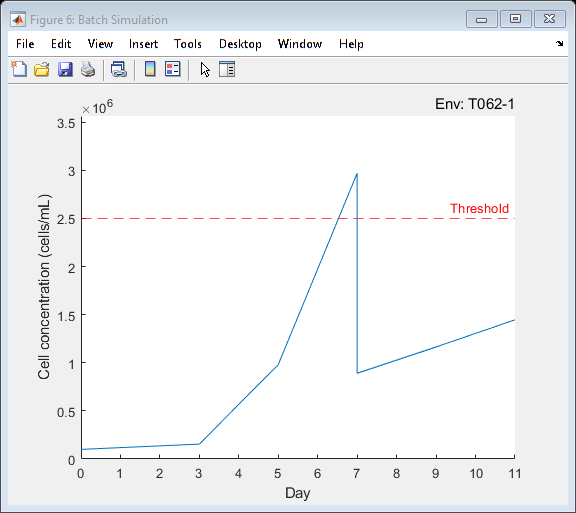

env3 =   modelEnv241 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T031-1"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×66 double]
                     numdonors: 8
                     foldExMap: [5×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


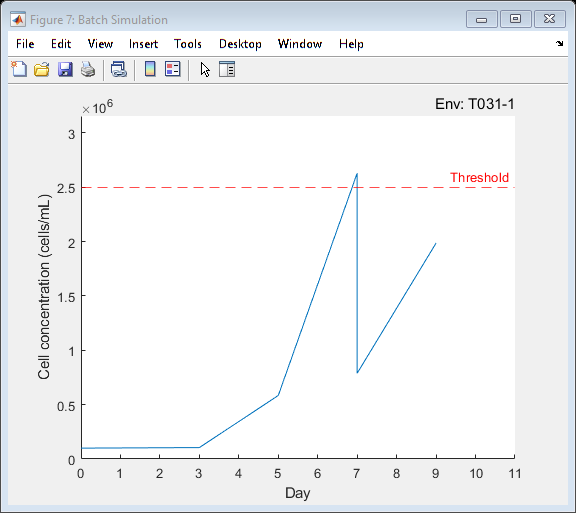

env3 =   modelEnv241 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T031-2"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×66 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


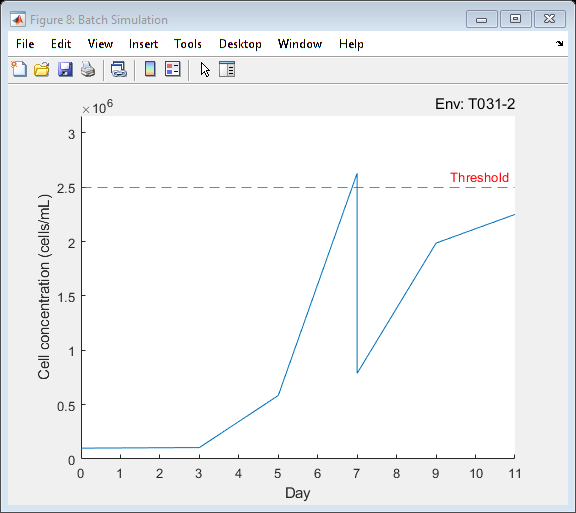

env3 =   modelEnv241 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T052-1"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×66 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


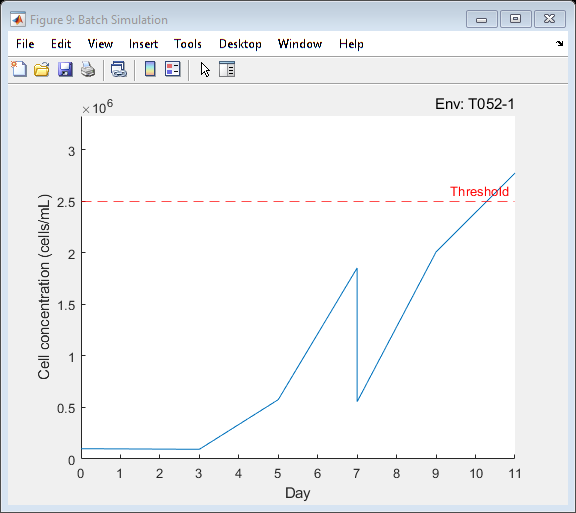

env3 =   modelEnv241 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T038-1"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×66 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


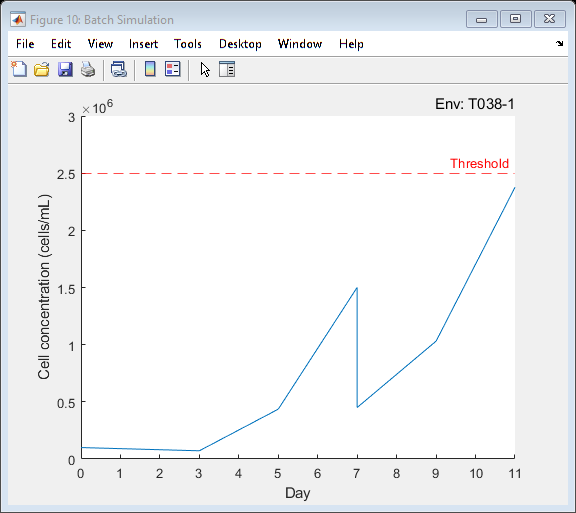

env3 =   modelEnv241 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T036-1"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×66 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


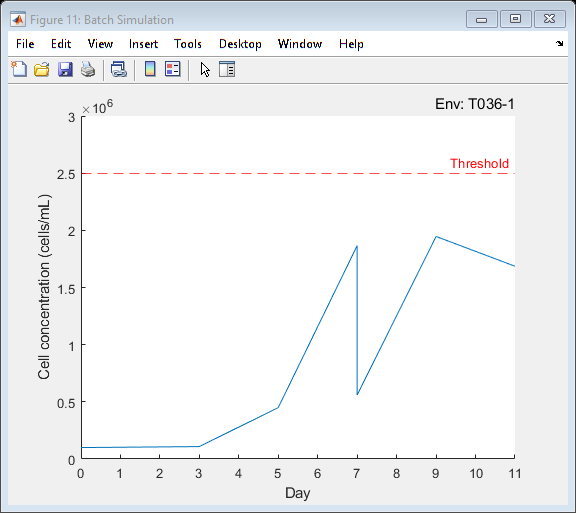

env3 =   modelEnv241 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T036-2"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×66 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


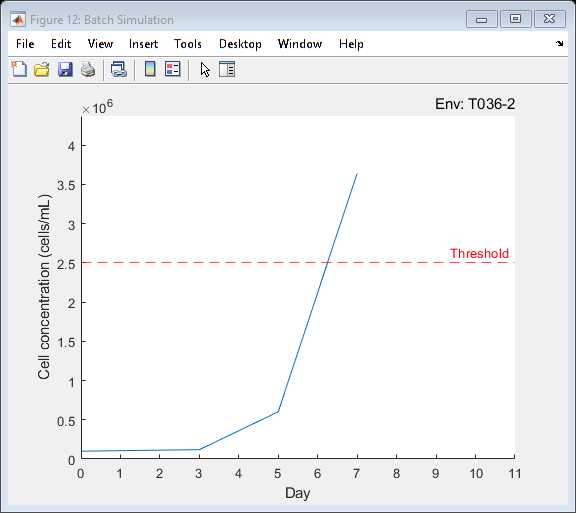

env3 =   modelEnv241 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T036-3"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×66 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


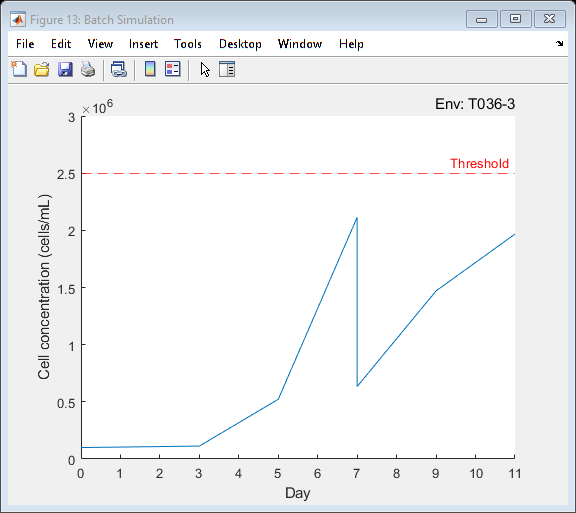

env3 =   modelEnv241 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T066-1"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×66 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


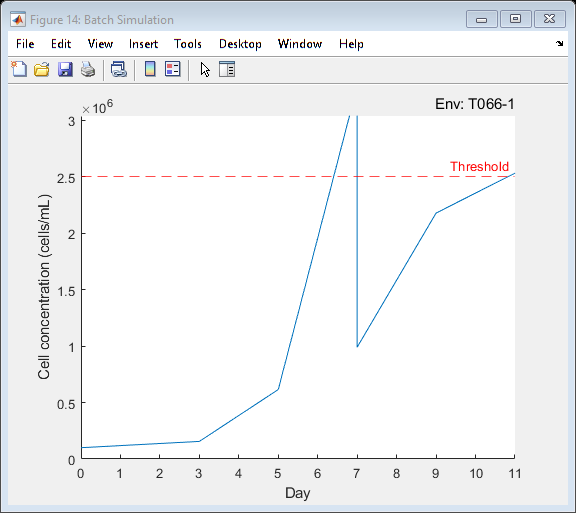

env3 =   modelEnv241 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T066-2"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×66 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


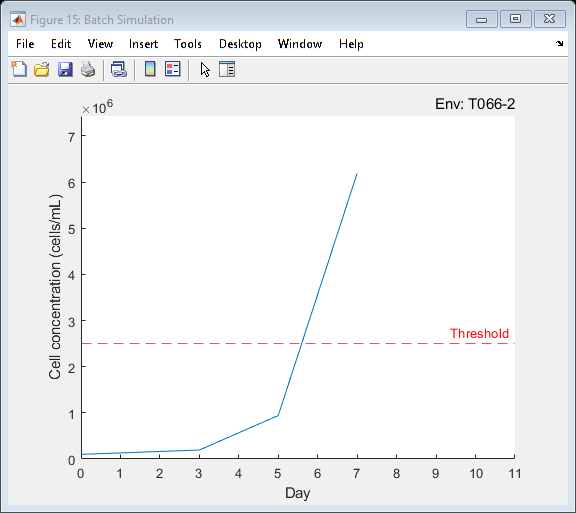

env3 =   modelEnv241 with properties:

                     useCustom: 1
                        expLen: 6
                     modelInfo: "T066-3"
                       initcon: [400000 420000 440000 460000 480000 500000 520000 540000 560000 580000 600000]
                   foldExModel: [6×66 double]
                     numdonors: 8
                     foldExMap: [6×1 double]
                  initialState: [0.1 1]
        concentrationThreshold: 2.5
    concentrationStopThreshold: 3.5
                       Reward1: 1
                      Penalty1: -2.5
                 timeStepStart: 0
                      timeStep: 0
                        Figure: []
             ConcentrationPlot: []
                         State: [0.5 1]
                       diluted: 0
                 overthreshold: 0


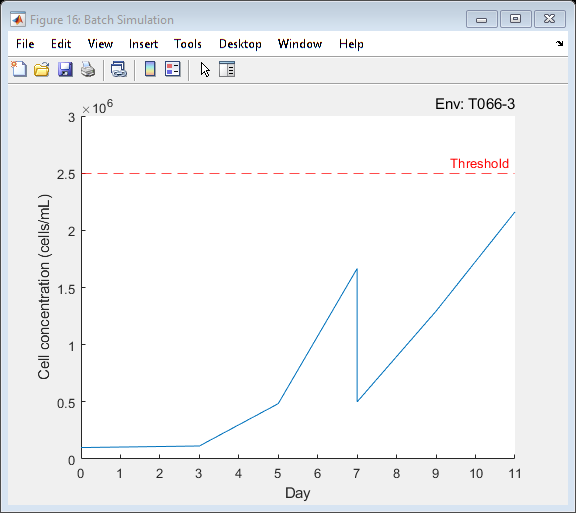

% dqnagent = load("agent_248_hailmary"+seed,"dqnagent").dqnagent
[simulationPlots,simulationResults] = simwithset(rawfoldincs,rawinitcons,rawdonornames,qagent);

[rewardMatrix,totalRewards,totalReward,averageReward] = calculatescore(6,simulationResults)

rewardMatrix =             0       0.1078        0.153       0.1358       0.1548       0.1052       0.1052        0.094       0.0718      0.10855        0.119       0.1131      0.15582       0.1952      0.11377
            1         0.66      0.70622      0.58019      0.98152      0.58439      0.58439        0.576        0.436      0.45014      0.60241      0.52239      0.61515      0.94286      0.48429
            2      -1.9556     -0.92524       2.2523      0.61578       1.9809       1.9809       1.8539       1.5015       1.8664      -2.0732       2.1147     -0.70038      -12.276        1.667
            3            0     -0.18289      -1.3998      -1.3358     -0.51343     -0.51343     -0.49112      -1.4691     -0.55367            0      -1.0296     -0.32186            0      -1.2065
            4            0            0       1.5152        1.447            0       2.2503       1.4097       2.3763        1.686            0       1.9675       2.3756            0       2.1615


totalRewards =       -1.1878     -0.24891       3.0838       1.8633       2.1571       4.4073       3.4425       2.9165       3.5573      -1.3518       3.6882       2.1243      -11.138       3.2202


totalReward =        16.534


averageReward =         1.181


writematrix(rewardMatrix,"Hyperparameter Tuning/LBF/rewardMatrix_2481_"+agentnumber+".xlsx")
writematrix(totalRewards,"Hyperparameter Tuning/LBF/totalRewards_2481_"+agentnumber+".xlsx")

% % Training with updates
% qagent1 = load("Hyperparameter Tuning/LBF/agent_2481"+agentnumber,"qagent").qagent
% qagent1.UseExplorationPolicy = true;
% qagent1.AgentOptions.EpsilonGreedyExploration.EpsilonMin = 0.001;
% qagent1.AgentOptions.EpsilonGreedyExploration.Epsilon = 0.001;
% [trainWithSetResults,trainPlots, trainSimResults] = trainwithset(rawfoldincs,rawinitcons,rawdonornames,dqnagent1);
% [rewardMatrix1,totalRewards1,totalReward1,averageReward1] = calculatescore(6,trainSimResults)
% save("Hyperparameter Tuning/LBF/agent_2481"+agentnumber+"_1","qagent1")

function [trialfoldincs, trialinitcons, trialdonornames] = initializedatasets(seed,allmodelfoldincs,modelinitcons,rawfoldincs,rawinitcons,rawdonornames,donoridxmap,donorlist)
    rng(seed);
    trainingvector = sort(randperm(9,6),"ascend");
    trainingset = donorlist(trainingvector)
    
    validationvector = [];
    for i=1:12
        if ismember(i,trainingvector)==false
            validationvector = [validationvector i];
        end
    end
    validationvector = sort(validationvector,"ascend");
    validationset = donorlist(validationvector)
    
    availmodelfoldincs = [allmodelfoldincs(:,1:numel(modelinitcons)*9)];
    
    trialmodelfoldincs = [];
    for i=trainingvector
        trialmodelfoldincs = [trialmodelfoldincs availmodelfoldincs(:,(numel(modelinitcons)*(i-1)+1):(numel(modelinitcons)*(i-1)+numel(modelinitcons)))];
    end    
        
    writematrix(trialmodelfoldincs, "modelfoldincs.txt")
    
%     trialfoldincs = [];
%     trialinitcons = [];
%     trialdonornames = [];
%     for i=validationvector
%         trialfoldincs = [trialfoldincs rawfoldincs(:,donoridxmap{i})];
%         trialinitcons = [trialinitcons rawinitcons(donoridxmap{i})];
%         % POTENTIALLY BETTER IF ALL NORMALIZED TO 500000
%         trialdonornames = [trialdonornames rawdonornames(donoridxmap{i})];
%     end
end 

function qagent = qinittraining(seed,numdonors,epsilondecay,numepisodes,learnrate,tilesperday)
    rng(0);    
    % create first environment
    env = modelEnv241;
    env.useCustom = false;
    env.numdonors = numdonors;
    obs = getObservationInfo(env);
    acts = getActionInfo(env);
    validateEnvironment(env)
    
    % hyperparameters
    discountFactor = 1;
    epsilon = 1;
    
    criticOpts = rlOptimizerOptions('LearnRate',learnrate);

    Xs = @(obs,acts) tileBsFcn2(obs,acts,tilesperday);
    numtiles = tilesperday*5*6;
    W0 = zeros(numtiles,1);
    qfunctionoptions = rlRepresentationOptions;
    % qfunction = rlQValueRepresentation(qtable,obs,acts)
    qfunction = rlQValueRepresentation({Xs,W0},obs,acts,qfunctionoptions);
    
    qagentoptions = rlQAgentOptions;
    qagentoptions.DiscountFactor = discountFactor;
    qagentoptions.EpsilonGreedyExploration.Epsilon = epsilon;
    qagentoptions.EpsilonGreedyExploration.EpsilonDecay = epsilondecay;
    qagentoptions.CriticOptimizerOptions = criticOpts;
    qagent = rlQAgent(qfunction,qagentoptions);
    
    
    trainopts = rlTrainingOptions;
    trainopts.MaxEpisodes = numepisodes;
    trainopts.StopTrainingCriteria = "EpisodeCount";
    trainopts.StopTrainingValue = numepisodes;
%     trainopts.StopTrainingCriteria = "AverageReward";
%     trainopts.StopTrainingValue = 15;
    %trainopts.Plots = 'none';
    %trainopts.Verbose = true;
    
    plot(env)
    results = train(qagent,env,trainopts);
end

function [plots,experiences] = simwithset(foldExMaps,day3cons,donornames,sarsaagent3)
    plots = cell(size(foldExMaps,2),1);
    experiences = cell(size(foldExMaps,2),1);
    for i=1:size(foldExMaps,2)
        %creating foldexmap
        foldExMap1 = foldExMaps(:,i);
        foldExMap1 = foldExMap1(~isnan(foldExMap1));
        idx = foldExMap1==1;
        idx(1) = false;
        foldExMap1(idx) = [];
        
        %creating new env
        env3 = modelEnv241;
        env3.useCustom = true;
        env3.foldExMap = foldExMap1;
        %NORMALIZED INIT CONS
        %
        env3.initialState = [100000/1000000,1];
        env3.modelInfo = donornames(i)
        validateEnvironment(env3)
        
        % plot now
        plot(env3);
        experiences{i} = sim(sarsaagent3,env3);
        plots{i} = env3.Figure;
    end
end

function [results3,plots,experiences] = trainwithset(foldExMaps,day3cons,donornames,sarsaagent3)
    results3 = cell(size(foldExMaps,2),1);
    plots = cell(size(foldExMaps,2),1);
    experiences = cell(size(foldExMaps,2),1);
    for i=1:size(foldExMaps,2)
        %creating foldexmap
        foldExMap1 = foldExMaps(:,i);
        foldExMap1 = foldExMap1(~isnan(foldExMap1));
        idx = foldExMap1==1;
        idx(1) = false;
        foldExMap1(idx) = [];

        %creating new env
        env3 = modelEnv241;
        env3.useCustom = true;
        env3.foldExMap = foldExMap1;
        env3.initialState = [100000/1000000,1];
        env3.modelInfo = donornames(i)
        validateEnvironment(env3)
        
        trainopts1 = rlTrainingOptions;
        trainopts1.StopTrainingCriteria = "EpisodeCount";
        trainopts1.StopTrainingValue = 1;
        trainopts1.Plots = 'none';

        %train
        plot(env3);
        results3{i} = train(sarsaagent3,env3,trainopts1);
        plot(env3);
        experiences{i} = sim(sarsaagent3,env3);
        plots{i} = env3.Figure;
    end
end

function [rewardMatrix,totalRewards,totalReward,averageReward] = calculatescore(maxSeriesLength,simulationResults)
    maxSeriesLength = 5;
    rewardMatrix = [0:(maxSeriesLength-1)]';
    for i=1:size(simulationResults,1)
        seriesRewards = simulationResults{i}.Reward.Data;
        if size(seriesRewards,1)<maxSeriesLength
            numZeros = maxSeriesLength - size(seriesRewards,1);
            for j=1:numZeros
                seriesRewards = [seriesRewards; 0];
            end
        end
        rewardMatrix = [rewardMatrix seriesRewards];
    end
    totalRewards = [];
    for i=2:size(rewardMatrix,2)
        totalRewards = [totalRewards sum(rewardMatrix(:,i))];
    end
    totalReward = sum(totalRewards);
    averageReward = mean(totalRewards);
end

function Xex = tileBsFcn2(obs,acts,tilesperday)
    actions = [0.18 0.21 0.24 0.27 0.3 1];
    numactions = numel(actions);
    resolution = 18000000/tilesperday;
    bounds1 = 0:resolution:18000000;
    bounds2 = 0:resolution:18000000;
    
    Xex = zeros(((numel(bounds1)-1)*3+(numel(bounds2)-1)*2),numactions);
    
    for i=1:(numactions)
        % day 3
        for a=1:(numel(bounds1)-1)
            Xex(a,i) = all([obs(1)>bounds1(a);obs(1)<=bounds1(a+1);obs(2)==1;acts(1)==(actions(i))]);
        end
        % day 5
        for a=1:(numel(bounds1)-1)
            Xex(a+(numel(bounds1)-1),i) = all([obs(1)>bounds1(a);obs(1)<=bounds1(a+1);obs(2)==2;acts(1)==(actions(i))]);
        end
        % day 7
        for a=1:(numel(bounds1)-1)
            Xex(a+(numel(bounds1)-1)*2,i) = all([obs(1)>bounds1(a);obs(1)<=bounds1(a+1);obs(2)==3;acts(1)==(actions(i))]);
        end 
        % day 9
        for b=1:(numel(bounds2)-1)
            Xex(b+(numel(bounds1)-1)*3,i) = all([obs(1)>bounds2(b);obs(1)<=bounds2(b+1);obs(2)==4;acts(1)==(actions(i))]);
        end
        % day 11
        for b=1:(numel(bounds2)-1)
            Xex(b+(numel(bounds1)-1)*3+(numel(bounds2)-1),i) = all([obs(1)>bounds2(b);obs(1)<=bounds2(b+1);obs(2)==5;acts(1)==(actions(i))]);
        end    
    end
    
    Xex=reshape(Xex,[numel(Xex),1]);
end